%% =========================================================================
% LIMPIEZA DE MEMORIA
clear all; close all; clc;
%% =========================================================================

% FASE 1: IMPORTAR EL GEMELO DIGITAL
disp('1. Cargando el modelo URDF...');

1. Cargando el modelo URDF...


robot = importrobot('urdf/brazo_limpio.urdf');

% --- AÑADIR EL TCP ---
tcp = rigidBody('tcp_punta_garra');
union_tcp = rigidBodyJoint('fix_tcp', 'fixed');
setFixedTransform(union_tcp, trvec2tform([0.12, 0, 0])); 
tcp.Joint = union_tcp;
addBody(robot, tcp, 'End_1');

nombre_efector = 'tcp_punta_garra';
robot.DataFormat = 'column'; 


%% =========================================================================
% FASE 2: GENERACIÓN DE DATOS (ELBOW-UP FORZADO)
% =========================================================================
num_muestras = 100000;
disp(['2. Generando ', num2str(num_muestras), ' muestras espaciales en 9D...']);

2. Generando 100000 muestras espaciales en 9D...



limites_rad = [
     0.0000,  3.1416; % joint_1 (Base)
    -0.9337,  2.2078; % joint_2 (Hombro)
    -1.2950,  1.8465; % joint_3 (Codo)
    -1.5708,  1.5708; % joint_4 (Muñeca elevación)
    -1.2915,  1.8500  % joint_5 (Muñeca giro)
];

% [CORRECCIÓN]: Forzamos Elbow-Up limitando el rango del codo en el entrenamiento
% Ajusta el 0.0 según hacia dónde doble físicamente tu modelo
limites_train = limites_rad;
limites_train(3, 1) = 0.0; % Solo valores positivos para el codo

angulos_train = zeros(num_muestras, 5);
for j = 1:5
    min_val = limites_train(j, 1);
    max_val = limites_train(j, 2);
    angulos_train(:, j) = min_val + rand(num_muestras, 1) * (max_val - min_val);
end

datos_entrada_train = zeros(num_muestras, 9); 

for i = 1:num_muestras
    config = angulos_train(i, :)';
    tform = getTransform(robot, config, nombre_efector);
    
    xyz = tform(1:3, 4)';
    euler_angles = rotm2eul(tform(1:3, 1:3)); % ZYX (Yaw, Pitch, Roll)
    
    vector_orientacion = [
        sin(euler_angles(1)), cos(euler_angles(1)), ...
        sin(euler_angles(2)), cos(euler_angles(2)), ...
        sin(euler_angles(3)), cos(euler_angles(3))      
    ];
    
    datos_entrada_train(i, :) = [xyz, vector_orientacion];
end
disp('Dataset 9D (Elbow-Up) completado exitosamente.');

Dataset 9D (Elbow-Up) completado exitosamente.



%% =========================================================================
% FASE 3 Y 4: ENTRENAMIENTO Y EXPORTACIÓN
% =========================================================================
disp('3. Configurando y entrenando la Red Neuronal...');

3. Configurando y entrenando la Red Neuronal...


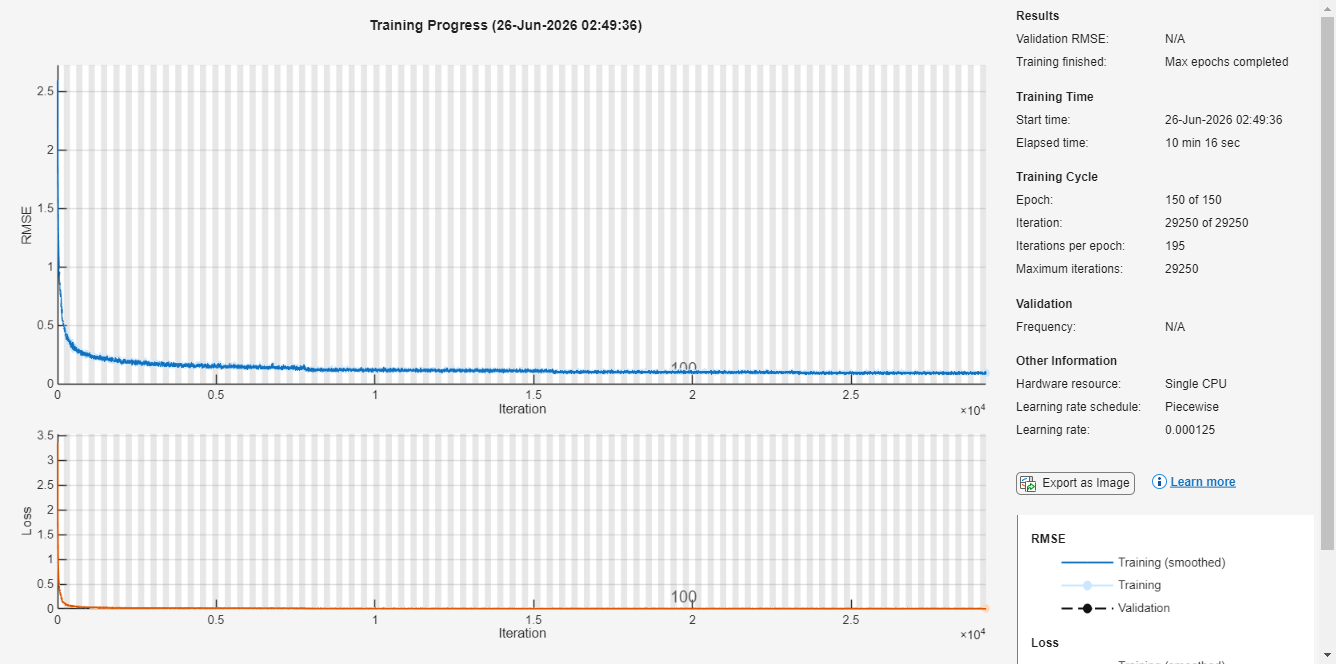

layers = [
    featureInputLayer(9, 'Normalization', 'zscore', 'Name', 'entrada_9d')
    fullyConnectedLayer(256, 'Name', 'oculta_1')
    reluLayer('Name', 'activacion_1')
    fullyConnectedLayer(256, 'Name', 'oculta_2')
    reluLayer('Name', 'activacion_2')
    fullyConnectedLayer(128, 'Name', 'oculta_3')
    reluLayer('Name', 'activacion_3')
    fullyConnectedLayer(5, 'Name', 'salida_angulos')
    regressionLayer('Name', 'salida')
];

options = trainingOptions('adam', ...
    'MaxEpochs', 150, ...
    'MiniBatchSize', 512, ...
    'InitialLearnRate', 0.001, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.5, ...
    'LearnRateDropPeriod', 40, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress', ...
    'Verbose', false);

red_ik = trainNetwork(datos_entrada_train, angulos_train, layers, options);

save('modelo_brazo.mat', 'red_ik');
disp('¡Modelo guardado!');

¡Modelo guardado!



%% =========================================================================
% FASE 6: MODO INTERACTIVO EN TIEMPO REAL (CORREGIDO)
% =========================================================================
disp('--- INICIANDO CONTROL INTERACTIVO ---');

--- INICIANDO CONTROL INTERACTIVO ---


fig_interactiva = figure('Name', 'Control Interactivo por IA');
ax = show(robot, homeConfiguration(robot));
hold on;
punto_objetivo = plot3(ax, 0, 0, 0, 'ro', 'MarkerSize', 12, 'LineWidth', 2, 'MarkerFaceColor', 'r');

while true
    fprintf('\n-----------------------------------\n');
    x_in = input('Coordenada X (m): ');
    if x_in == 999, close(fig_interactiva); break; end
    y_in = input('Coordenada Y (m): ');
    z_in = input('Coordenada Z (m): ');
    
    % [CORRECCIÓN]: Calculamos el Yaw natural acoplado a la base
    yaw_in = atan2(y_in, x_in); 
    
    % Asumimos que queremos la herramienta horizontal (Pitch 0) y sin girar (Roll 0)
    % Si el robot no puede alcanzar Pitch 0 en esa coordenada Z, el error subirá.
    pitch_in = 0; 
    roll_in = 0; 
    
    entrada_9d = [x_in, y_in, z_in, ...
                  sin(yaw_in), cos(yaw_in), ...
                  sin(pitch_in), cos(pitch_in), ...
                  sin(roll_in), cos(roll_in)];
    
    angulos_predichos = predict(red_ik, entrada_9d);
    
    config_interactiva = zeros(5, 1);
    for j = 1:5
        % Aseguramos los límites, usando limites_train para mantener el elbow-up
        config_interactiva(j) = max(limites_train(j,1), min(limites_train(j,2), angulos_predichos(j)));
    end
    
    set(punto_objetivo, 'XData', x_in, 'YData', y_in, 'ZData', z_in);
    show(robot, config_interactiva, 'Parent', ax, 'PreservePlot', false, 'FastUpdate', true);
    drawnow;
    
    tform_real = getTransform(robot, config_interactiva, nombre_efector);
    xyz_alcanzado = tform_real(1:3, 4)';
    error_mm = norm([x_in, y_in, z_in] - xyz_alcanzado) * 1000;
    
    title(ax, ['Error actual de la IA: ', num2str(error_mm, '%.2f'), ' mm']);
    fprintf('>> Movimiento ejecutado. Error físico: %.2f mm\n', error_mm);
end


-----------------------------------


>> Movimiento ejecutado. Error físico: 70.81 mm



-----------------------------------
